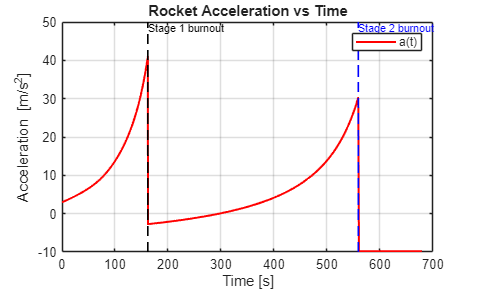

clc; clear; close all;

%% Two-stage rocket ODE simulation
% Solves altitude, velocity, and mass in three time intervals.

%% Physical constants and environment
g0 = 9.81;          % gravity [m/s^2]
rho0 = 1.225;       % sea level air density [kg/m^3]
H = 8500;           % scale height [m]
Cd = 0.5;           % drag coeff
A = 10.5;           % cross-sectional area [m^2]
useDrag = true;     % toggle drag

%% Stage 1 parameters
m0 = 549054;         % total initial mass [kg]
mp1 = 410900;        % stage 1 propellant [kg]
tBurn1 = 162;        % burn duration [s]
mdot1 = mp1/tBurn1;  % mass flow rate [kg/s]
Isp1 = 282;          % specific impulse [s]
T1 = mdot1*Isp1*g0;  % thrust [N]
mStruct1 = 25600;    % stage 1 dry mass jettisoned [kg]

%% Stage 2 parameters & coast phase
mp2 = 92670;         % stage 2 propellant [kg]
tBurn2 = 397;        % burn duration [s]
mdot2 = mp2/tBurn2;  % mass flow rate [kg/s]
Isp2 = 348;          % specific impulse [s]
T2 = mdot2*Isp2*g0;  % thrust [N]

tCoast = 120;        % coasting duration after burnout [s]

%% ODE settings and initial state
opts = odeset('RelTol', 1e-8, 'AbsTol', 1e-8);
y0 = [0; 0; m0];     % [altitude; velocity; mass]

%% Solve flight phases
% Phase 1: Stage 1 powered flight
[t1, Y1] = ode45(@(t,y) rocketODE(t, y, T1, mdot1, g0, Cd, A, rho0, H, useDrag), ...
                 [0, tBurn1], y0, opts);

% Boundary condition: keep position & speed, subtract dropped structural mass
y0Stage2 = [Y1(end,1); Y1(end,2); Y1(end,3) - mStruct1];

% Phase 2: Stage 2 powered flight
[t2, Y2] = ode45(@(t,y) rocketODE(t, y, T2, mdot2, g0, Cd, A, rho0, H, useDrag), ...
                 [t1(end), t1(end) + tBurn2], y0Stage2, opts);

% Phase 3: Unpowered coasting (thrust & mass loss = 0)
[t3, Y3] = ode45(@(t,y) rocketODE(t, y, 0, 0, g0, Cd, A, rho0, H, useDrag), ...
                 [t2(end), t2(end) + tCoast], Y2(end,:)', opts);

%% Combine outputs
% Remove duplicate boundary entries
t = [t1; t2(2:end); t3(2:end)];
Y = [Y1; Y2(2:end,:); Y3(2:end,:)];

h = Y(:,1);  % altitude [m]
v = Y(:,2);  % velocity [m/s]
m = Y(:,3);  % mass [kg]

t1End = t1(end);
t2End = t2(end);

%% Compute acceleration array for plotting
a = zeros(size(t));
for i = 1:length(t)
    if t(i) <= t1End
        Ti = T1;
    elseif t(i) <= t2End
        Ti = T2;
    else
        Ti = 0;
    end

    if useDrag
        rho = airDensity(h(i), rho0, H);
        drag = 0.5 * rho * Cd * A * v(i) * abs(v(i));
    else
        drag = 0;
    end

    a(i) = (Ti - m(i)*g0 - drag) / m(i);
end

%% Plots
figure;
plot(t, a, 'r', 'LineWidth', 1.5); grid on; hold on;
drawVLine(t1End, 'k', 'Stage 1 burnout');
drawVLine(t2End, 'b', 'Stage 2 burnout');
xlabel('Time [s]'); ylabel('Acceleration [m/s^2]');
title('Rocket Acceleration vs Time'); legend('a(t)');

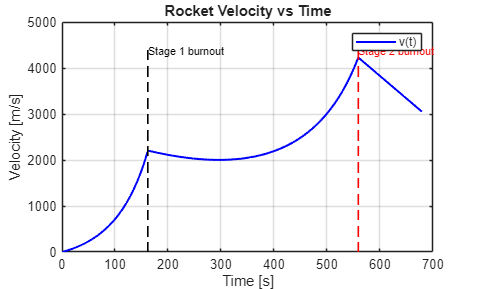


figure;
plot(t, v, 'b', 'LineWidth', 1.5); grid on; hold on;
drawVLine(t1End, 'k', 'Stage 1 burnout');
drawVLine(t2End, 'r', 'Stage 2 burnout');
xlabel('Time [s]'); ylabel('Velocity [m/s]');
title('Rocket Velocity vs Time'); legend('v(t)');

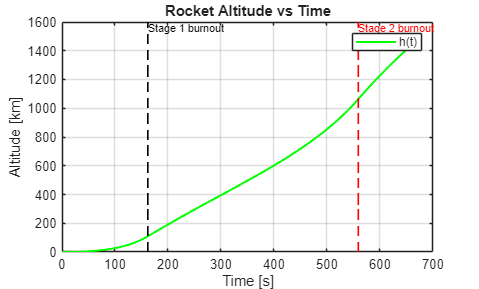


figure;
plot(t, h/1000, 'g', 'LineWidth', 1.5); grid on; hold on;
drawVLine(t1End, 'k', 'Stage 1 burnout');
drawVLine(t2End, 'r', 'Stage 2 burnout');
xlabel('Time [s]'); ylabel('Altitude [km]');
title('Rocket Altitude vs Time'); legend('h(t)');

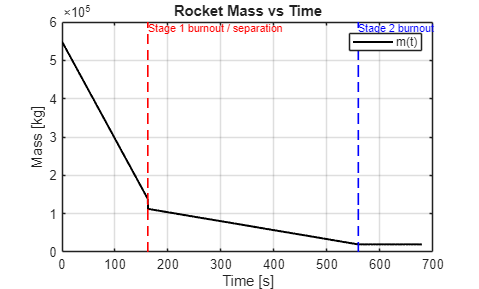


figure;
plot(t, m, 'k', 'LineWidth', 1.5); grid on; hold on;
drawVLine(t1End, 'r', 'Stage 1 burnout / separation');
drawVLine(t2End, 'b', 'Stage 2 burnout');
xlabel('Time [s]'); ylabel('Mass [kg]');
title('Rocket Mass vs Time'); legend('m(t)');


%% Print summary
disp(['Stage 1 burnout time = ', num2str(t1End), ' s']);

Stage 1 burnout time = 162 s


disp(['Stage 2 burnout time = ', num2str(t2End), ' s']);

Stage 2 burnout time = 559 s


disp(['Maximum altitude = ', num2str(max(h)/1000), ' km']);

Maximum altitude = 1500.0157 km


disp(['Maximum velocity = ', num2str(max(v)), ' m/s']);

Maximum velocity = 4228.7921 m/s


disp(['Final mass = ', num2str(m(end)), ' kg']);

Final mass = 19884 kg



%% Local Functions

function rho = airDensity(h, rho0, H)
    % exponential density model (clamp at ground level)
    h = max(h, 0);
    rho = rho0 * exp(-h/H);
end

function dy = rocketODE(~, y, T, mdot, g0, Cd, A, rho0, H, useDrag)
    % state vector: y(1)=altitude, y(2)=velocity, y(3)=mass
    h = y(1);
    v = y(2);
    m = y(3);

    if useDrag
        rho = airDensity(h, rho0, H);
        drag = 0.5 * rho * Cd * A * v * abs(v);
    else
        drag = 0;
    end

    accel = (T - m*g0 - drag) / m;
    dy = [v; accel; -mdot];
end

function drawVLine(xVal, colorSpec, labelText)
    % plot dashed vertical line (Octave / MATLAB compatible)
    yl = ylim();
    line([xVal, xVal], yl, 'Color', colorSpec, 'LineStyle', '--', 'LineWidth', 1.2);
    text(xVal, yl(2), labelText, 'VerticalAlignment', 'top', ...
         'HorizontalAlignment', 'left', 'FontSize', 8, 'Color', colorSpec);
end